 close all; clear; clc;

# Settling Time v4 (Thrust Curve, ramp up and down)

**file name**: STv4_TM15d_20180731_1.mlx

**keywords:** 

**date of test:** 20180731

**file created by:** 20180805, NAME

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** [C_T], [C_P], [C_Q]

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.00230295081674551;                  %[slugs/ft^3]

% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the data output from RC Benchmark has not been changed

load('STv4_TM15d.mat');
time = STv4_TM15d(:,1);                       % [sec]
PWM = STv4_TM15d(:,2);                        % [micro sec]
Q = STv4_TM15d(:,4);                          % [ft.lbf]
T = STv4_TM15d(:,5);                          % [lbf]
Input_V = STv4_TM15d(:,6);                    % [Volts]
Input_A = STv4_TM15d(:,7);                    % [Amps]
rot_speed_rad = STv4_TM15d(:,8);              % [rad/sec]
% convert to RPM for plotting purposes
rot_speed_rpm = rot_speed_rad ./ (pi/30);   % [RPM]
P_in_W = STv4_TM15d(:,9);                     % [Watts]
P_out_W = STv4_TM15d(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;                  % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff = STv4_TM15d(:,11);                 % [%]
Prop_Eff = STv4_TM15d(:,12);                  % [lbf/Watts]
Overall_Eff = STv4_TM15d(:,13);               % [lbf/Watts]  
Motor_Temp = STv4_TM15d(:,14);                % [F]


**Convert the following lines to code if this is a Settling Time script. Delete if not applicable**

Settling_time = STv4_TM15d(:,17); % [s]
Max_Acc = STv4_TM15d(:,18);      % [RPM]


## Thrust, Power, and Torque Coefficents

C_T = T ./ (p .* area * (rot_speed_rad * radius).^2);
C_P = P_out ./ (p .* area .* (rot_speed_rad .* radius).^3);
C_Q = Q ./ (p .* area .* (rot_speed_rad .* radius).^(2) .* radius);

## Plots

The following are standard charts. Remove, add, and edit as needed.

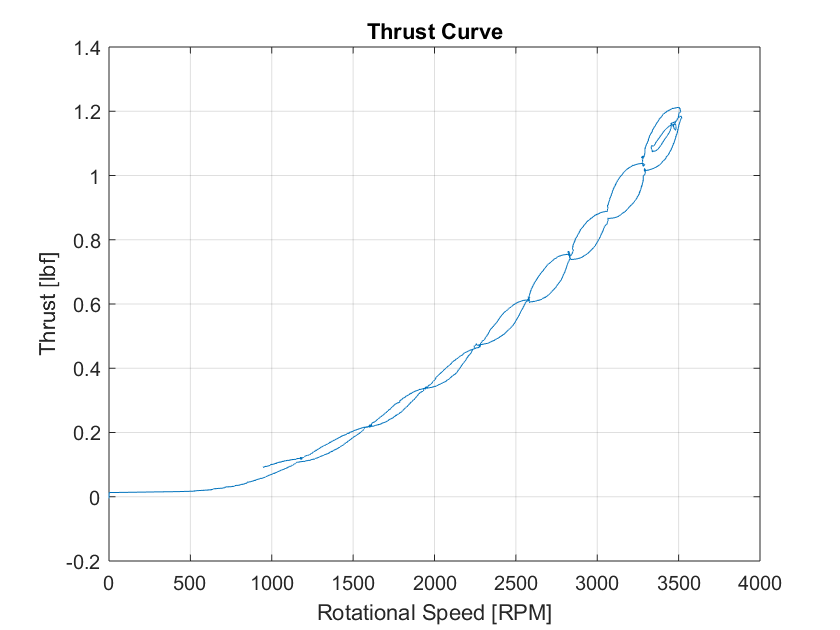

figure(1)
plot(rot_speed_rpm, T); title('Thrust Curve'); 
xlabel('Rotational Speed [RPM]'); ylabel('Thrust [lbf]'); grid('on');

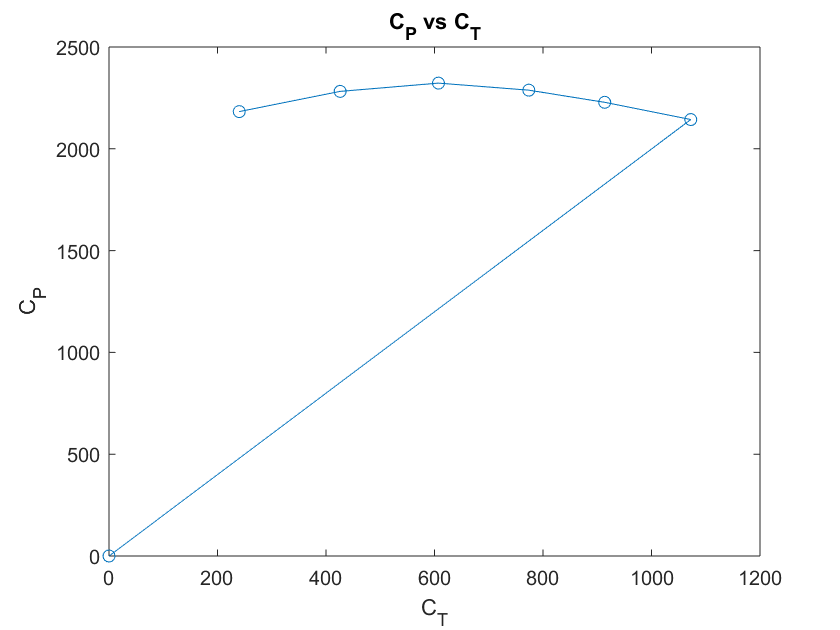


figure(2)
plot(C_T, C_P,'o-');
title('C_P vs C_T'); xlabel('C_T'); ylabel('C_P')

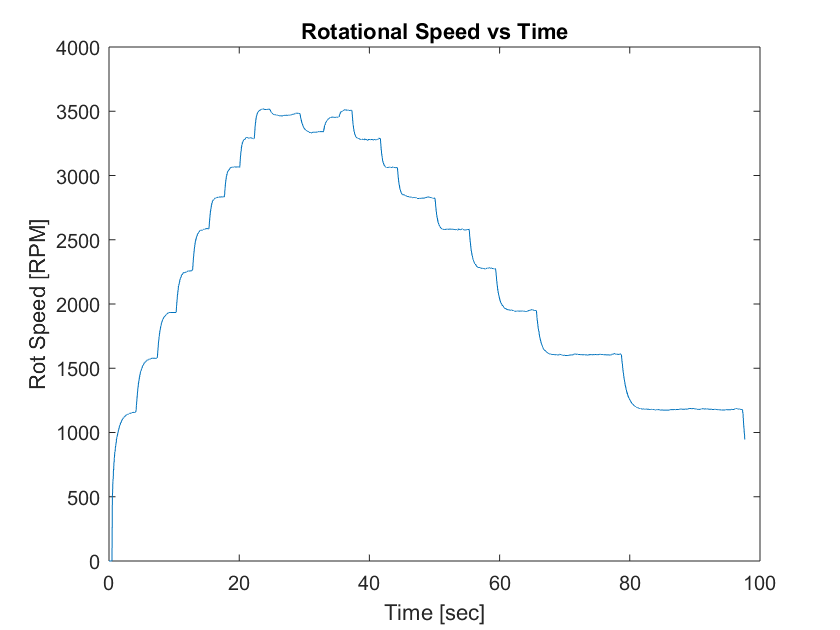


figure(3)
plot(time, rot_speed_rpm); title('Rotational Speed vs Time'); 
xlabel('Time [sec]'); ylabel('Rot Speed [RPM]')

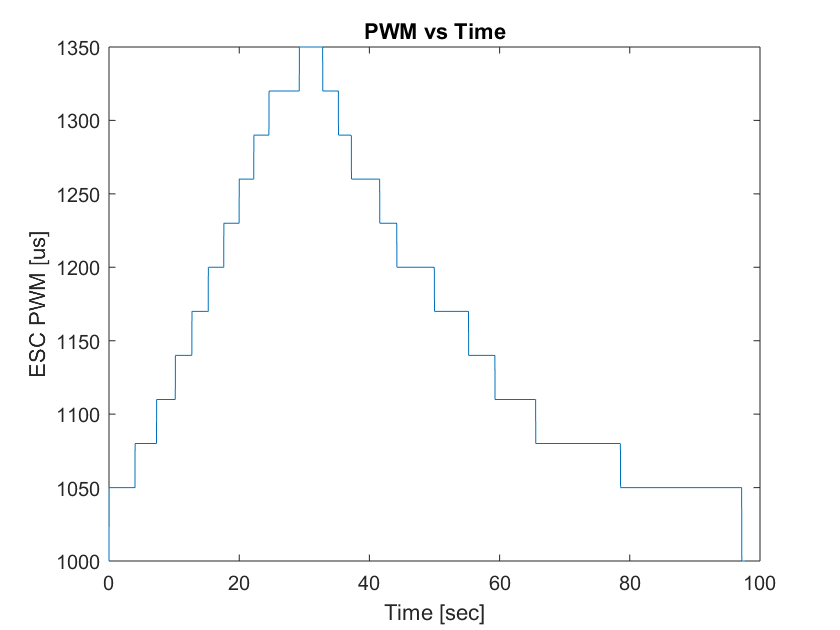


figure(4)
plot(time, PWM); title('PWM vs Time'); 
xlabel('Time [sec]'); ylabel('ESC PWM [us]');

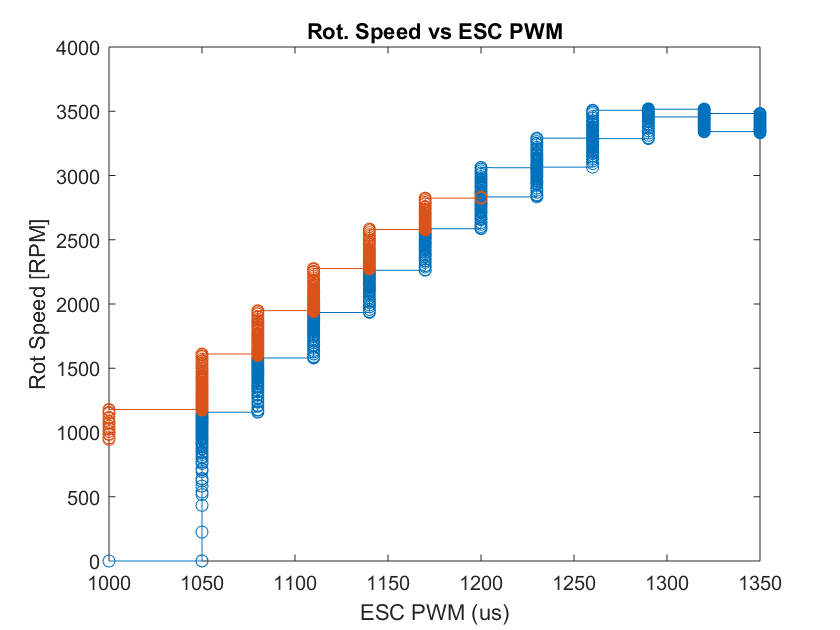


x = (1:2025);
y = (2025:4057);
figure(5)
plot(PWM(x), rot_speed_rpm(x), 'o-', PWM(y), rot_speed_rpm(y), 'o-'); title('Rot. Speed vs ESC PWM'); 
xlabel('ESC PWM (us)'); ylabel('Rot Speed [RPM]')

**Convert the following lines to code if this is a Settling Time script. Delete if not applicable**

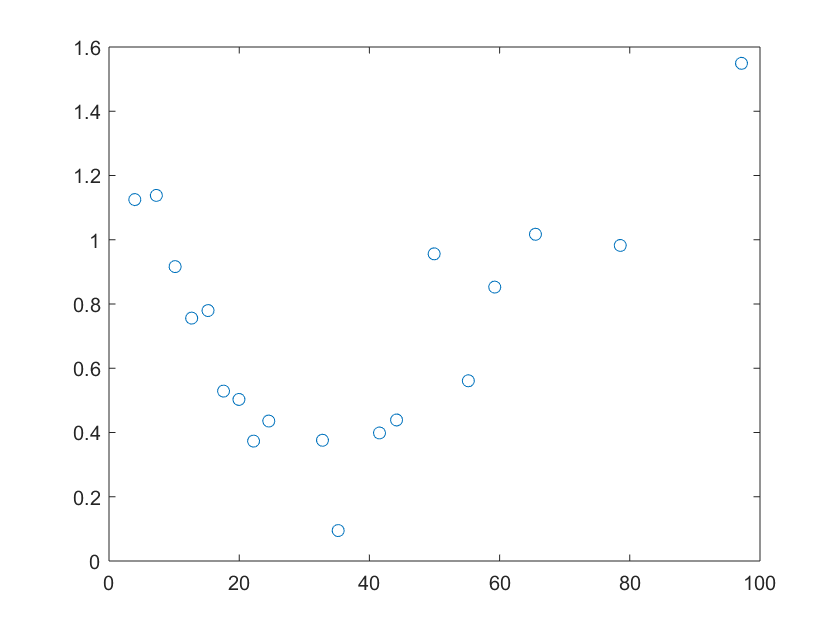

figure(6)
plot(time, Settling_time, 'o-');

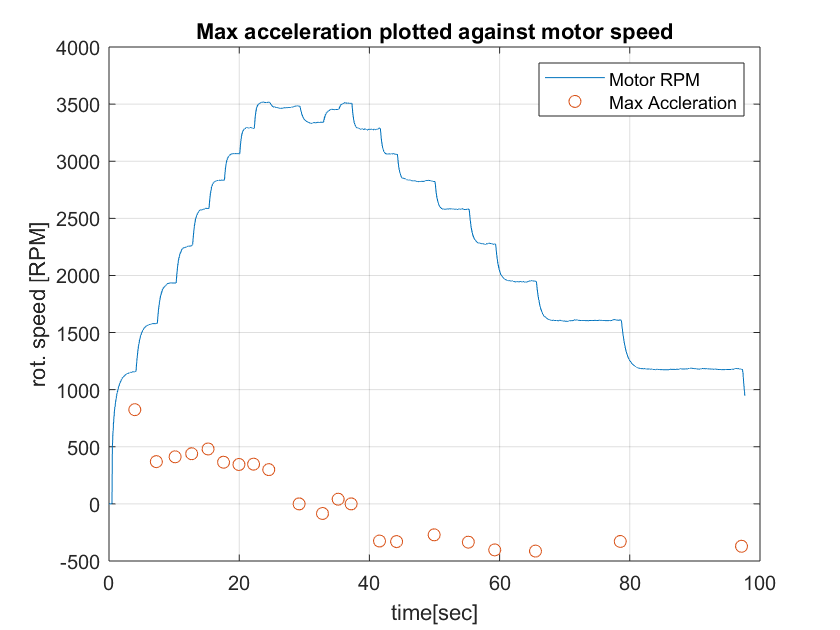


figure(7)
plot(time, rot_speed_rpm, time, Max_Acc, 'o');
title('Max acceleration plotted against motor speed')
xlabel('time[sec]'); ylabel('rot. speed [RPM]'); 
legend('Motor RPM', 'Max Accleration'); grid('on');

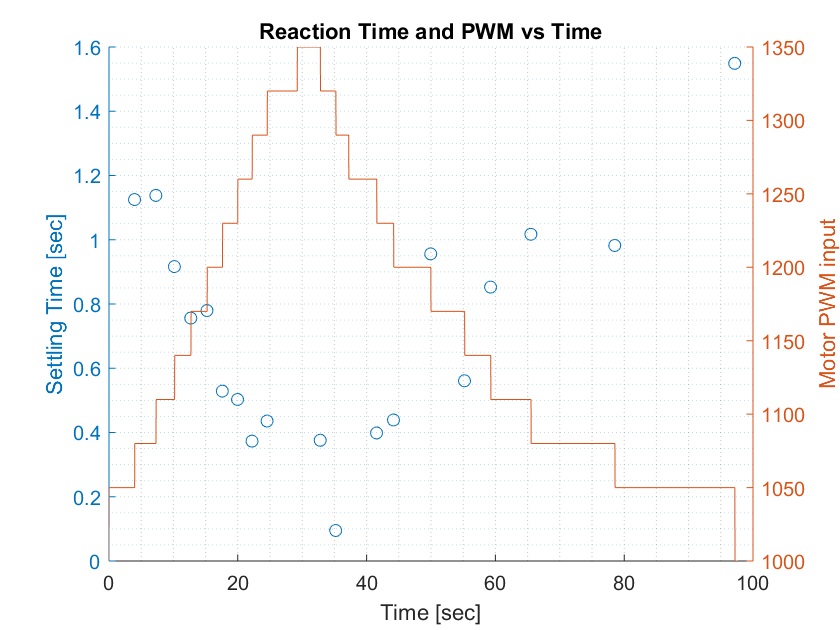

figure(8)
hold on
yyaxis left
plot(time,Settling_time, 'o-');
ylabel('Settling Time [sec]');
yyaxis right
plot(time, PWM);
ylabel('Motor PWM input');
title('Reaction Time and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

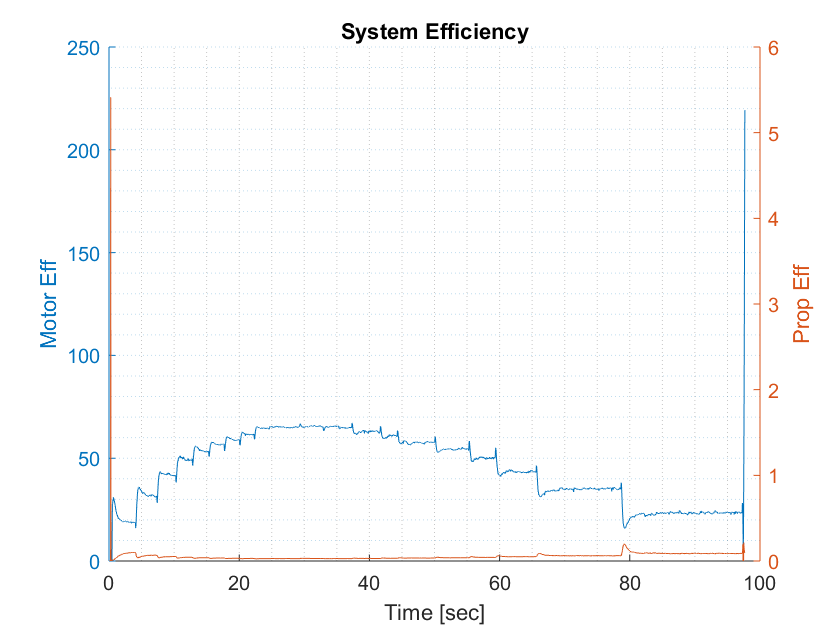



figure(9)
hold on
yyaxis left
plot(time,Motor_Eff);
ylabel('Motor Eff')
yyaxis right
plot(time, Prop_Eff);
ylabel('Prop Eff');
title('System Efficiency');
xlabel('Time [sec]');
grid('minor')
hold off

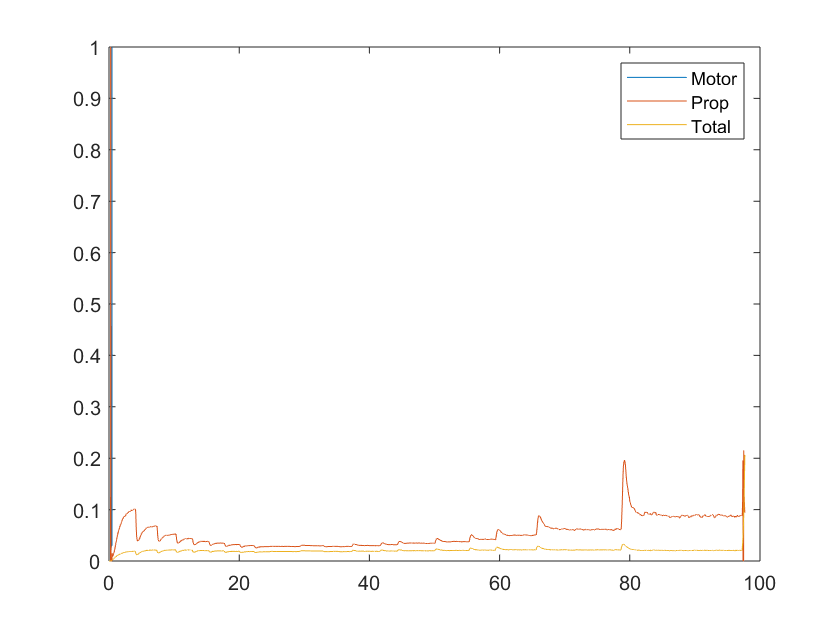



figure(10)
plot(time, Motor_Eff, time, Prop_Eff, time, Overall_Eff);
legend('Motor', 'Prop', 'Total');
ylim([0,1]);

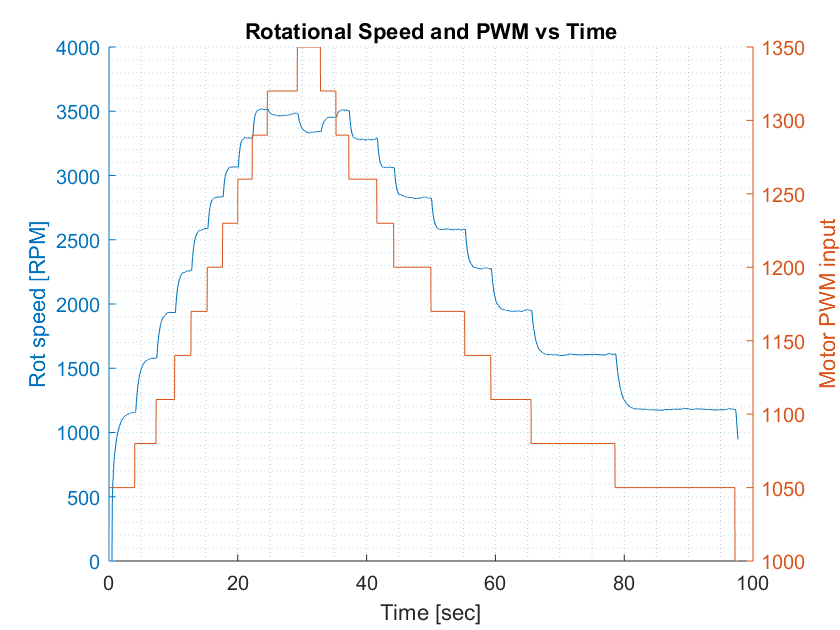




figure(11)
hold on
yyaxis left
plot(time, rot_speed_rpm);
ylabel('Rot speed [RPM]');
yyaxis right
plot(time, PWM);
ylabel('Motor PWM input');
title('Rotational Speed and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off